# Lane Detection

## Get Video

v = VideoReader('Data/black_car.mp4');

## Get frame

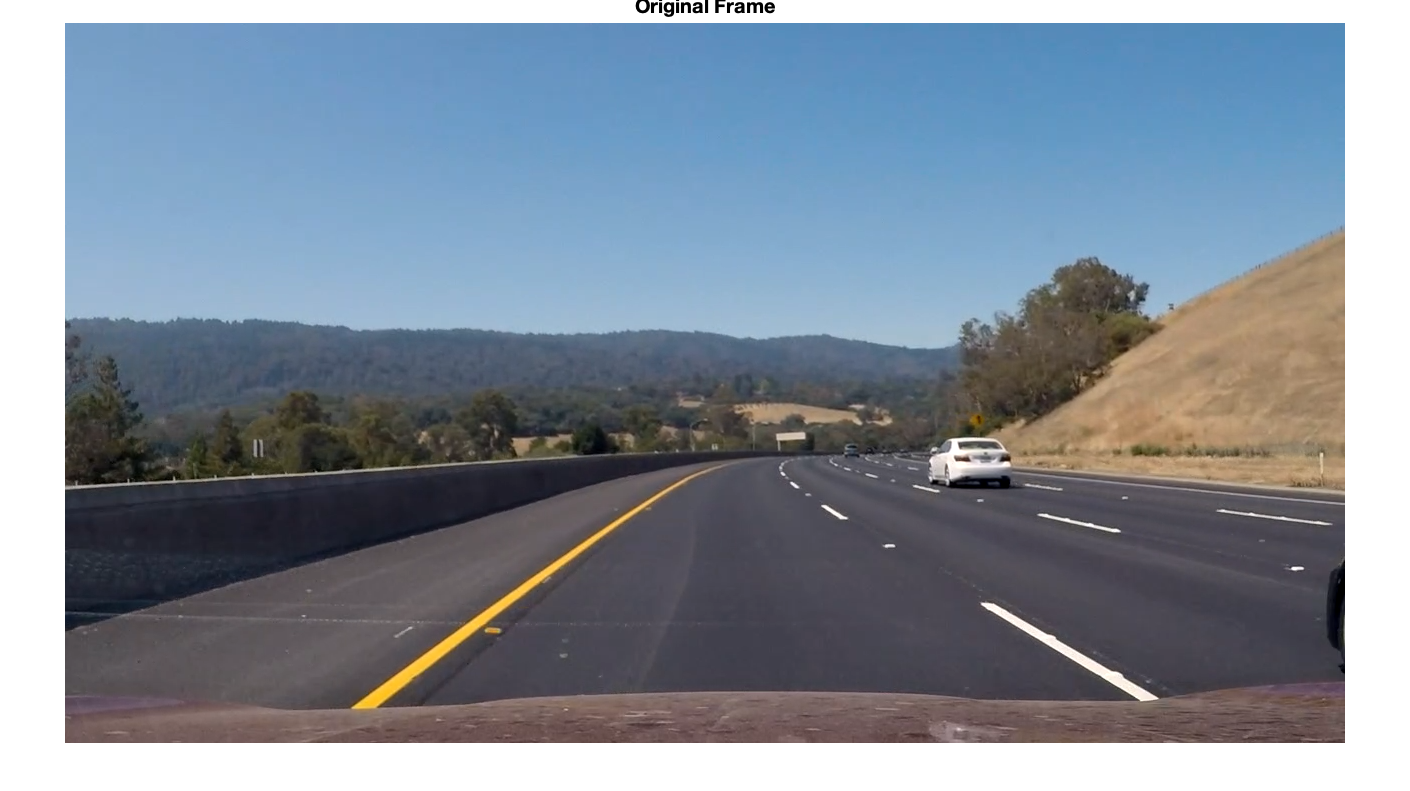

frame = readFrame(v);
imshow(frame);
title('Original Frame', 'FontSize', 20);

## Convert from RGB to HSV

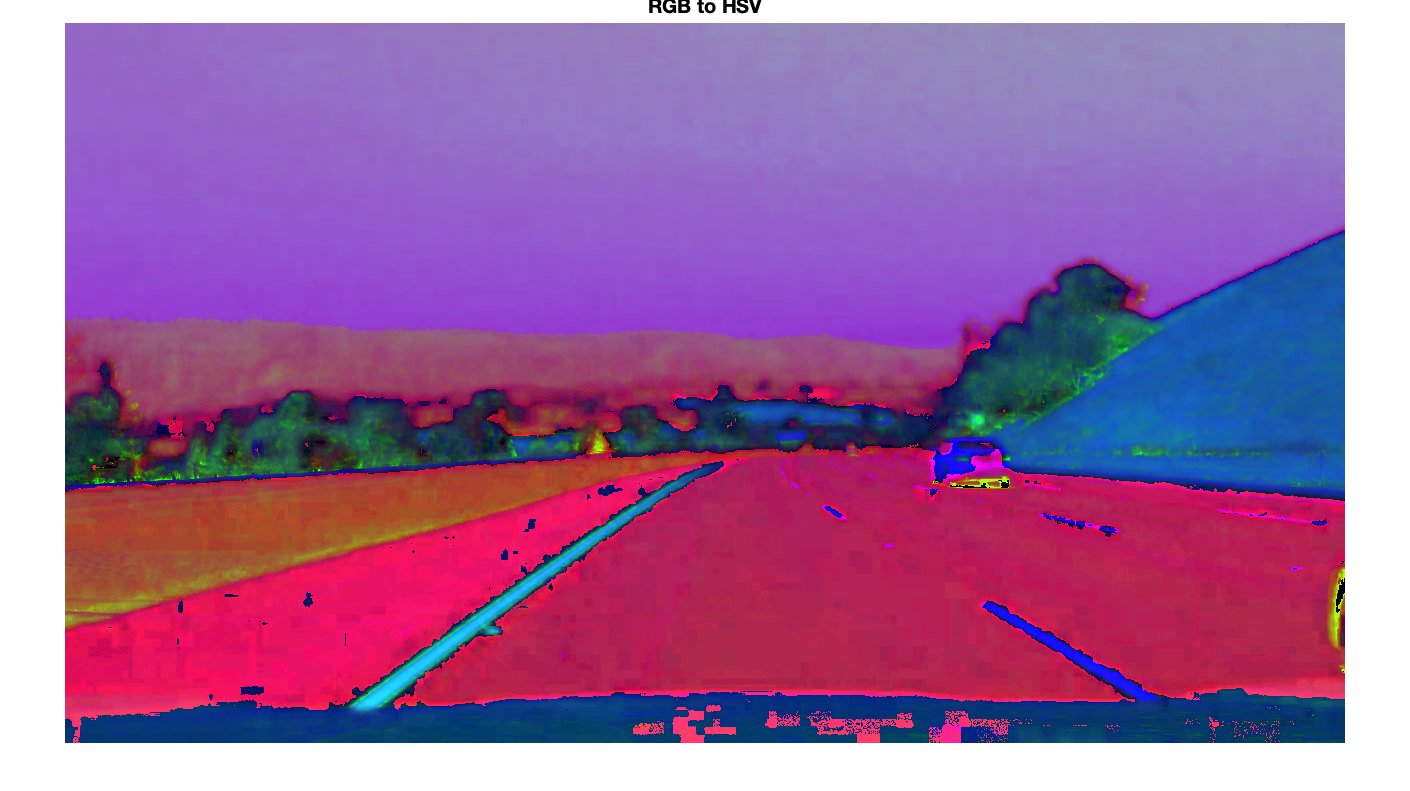

hsv = rgb2hsv(frame);
imshow(hsv);
title('RGB to HSV', 'FontSize', 20);

## Extract V channel from HSV

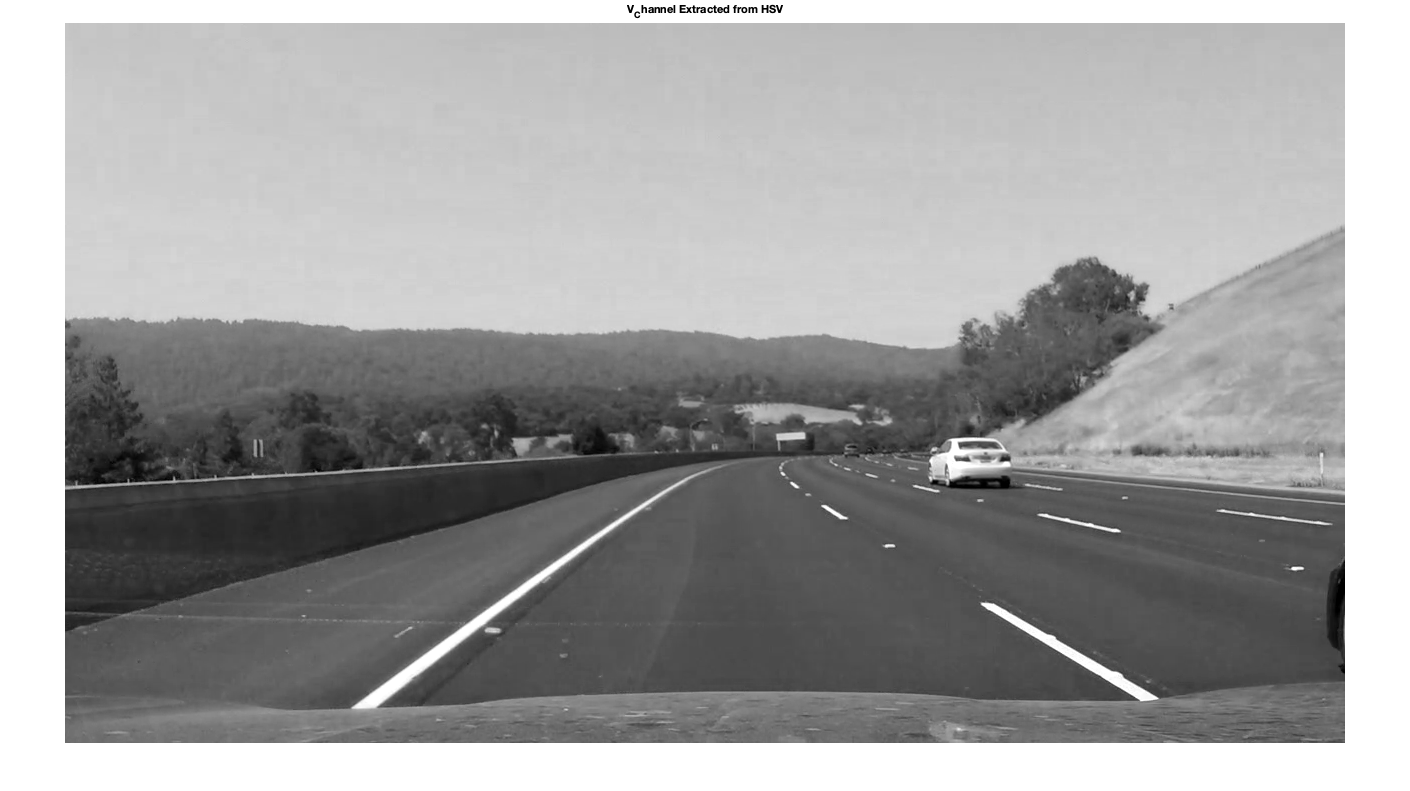

v_channel = hsv(:, :, 3);
imshow(v_channel);
title('V_Channel Extracted from HSV');

## Threshold Image

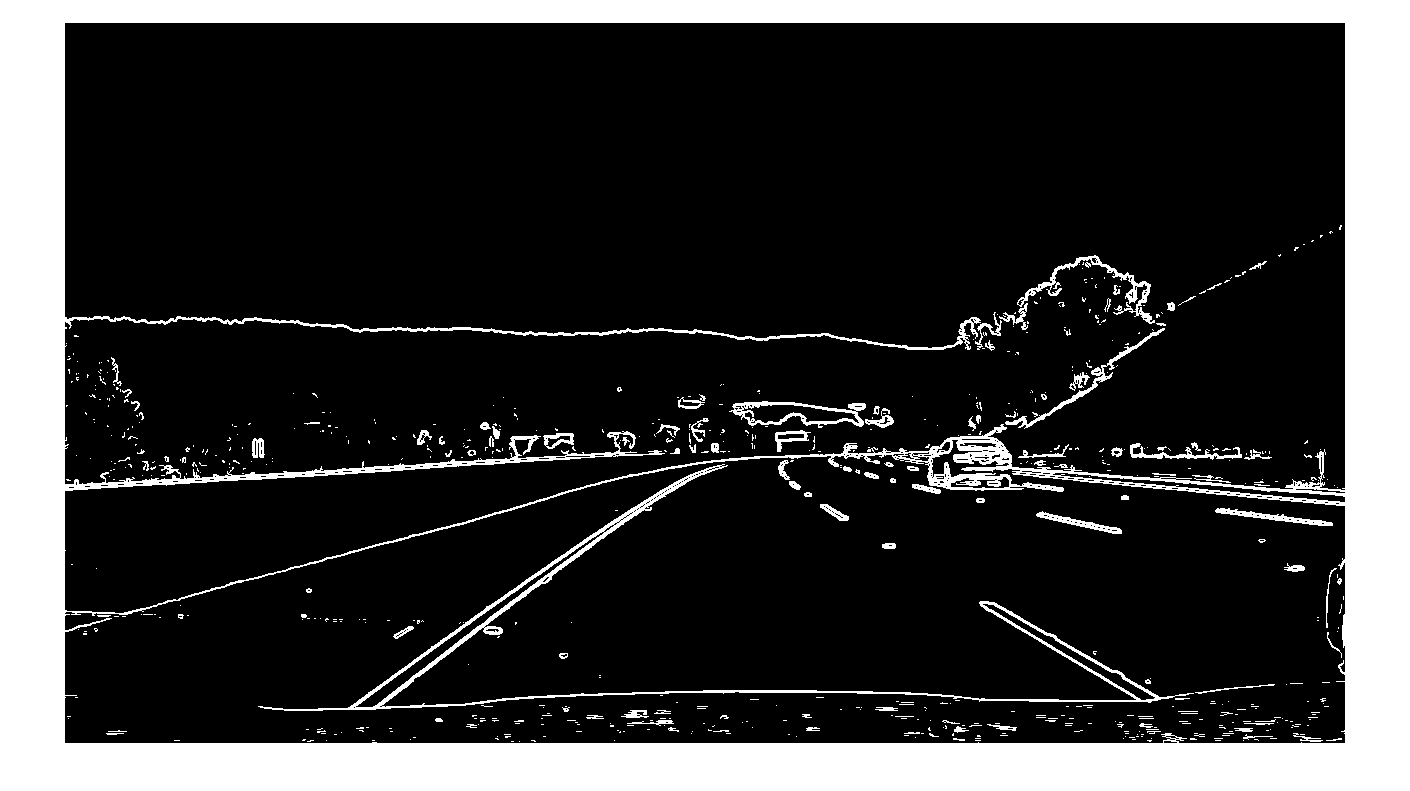

sobel = imgradient(v_channel, 'sobel');
a = imbinarize(sobel);
imshow(a);

## Mask Image

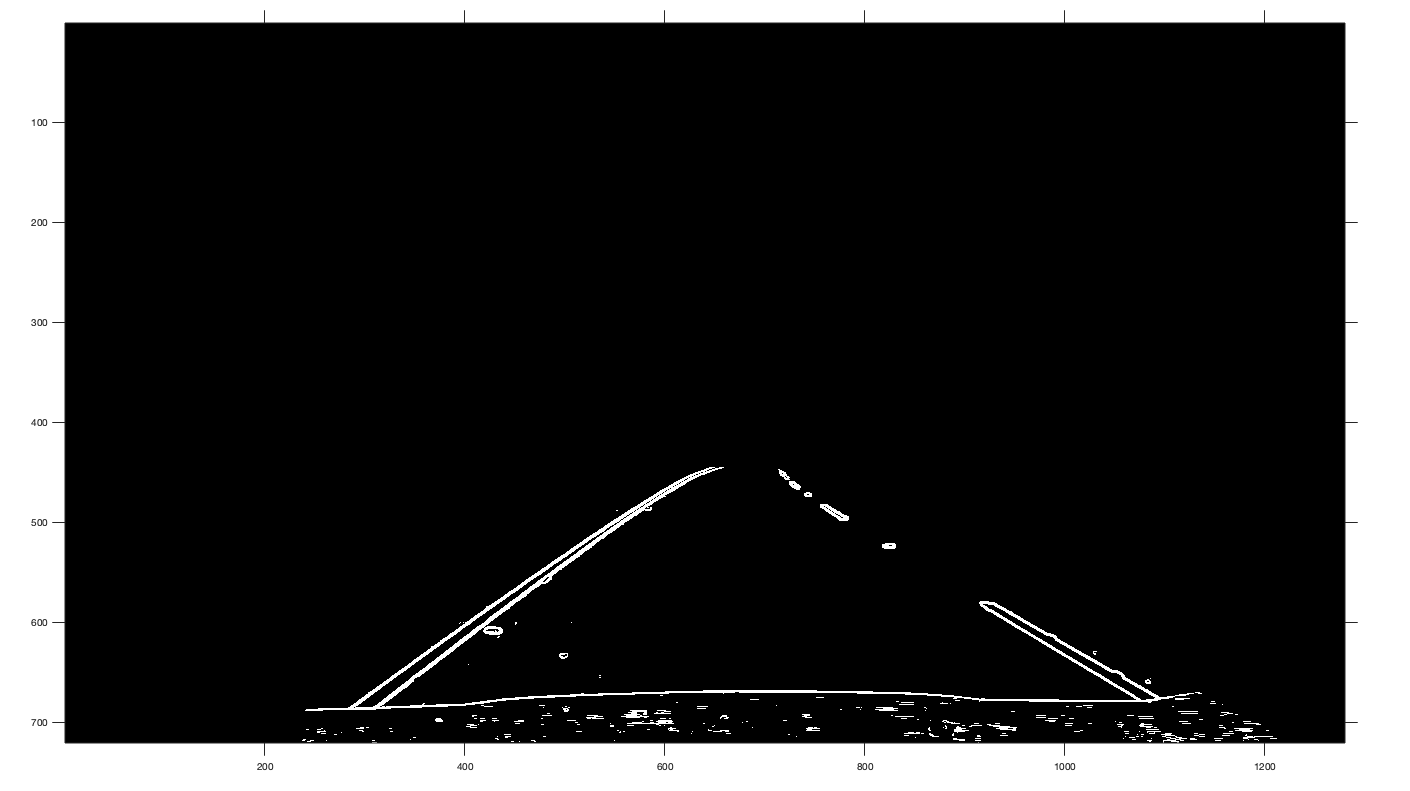

% region of interest points
dimens = size(a);
m = dimens(1);
n = dimens(2);
x_points = [710, 620, 190, 1230];
y_points = [444, 444, 720, 720];
mask = poly2mask(x_points, y_points, m, n);
masked = and(a, mask);
imshow(masked);
axis on;

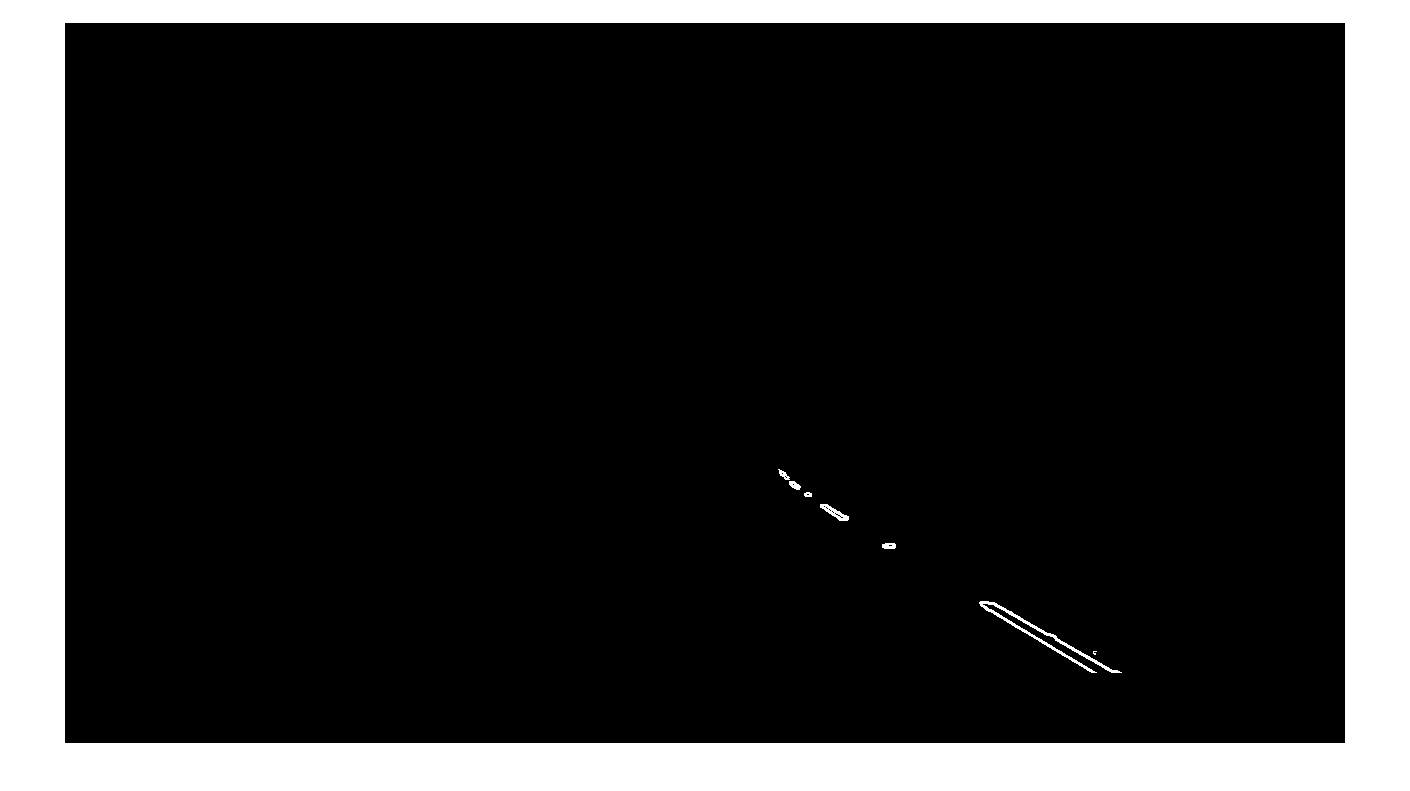

rl_x = [710, 680, 680, 1200];
rl_y = [200, 200, 650, 650];
rl_mask = poly2mask(rl_x, rl_y, m, n);
masked_right = and(masked, rl_mask);
imshow(masked_right)

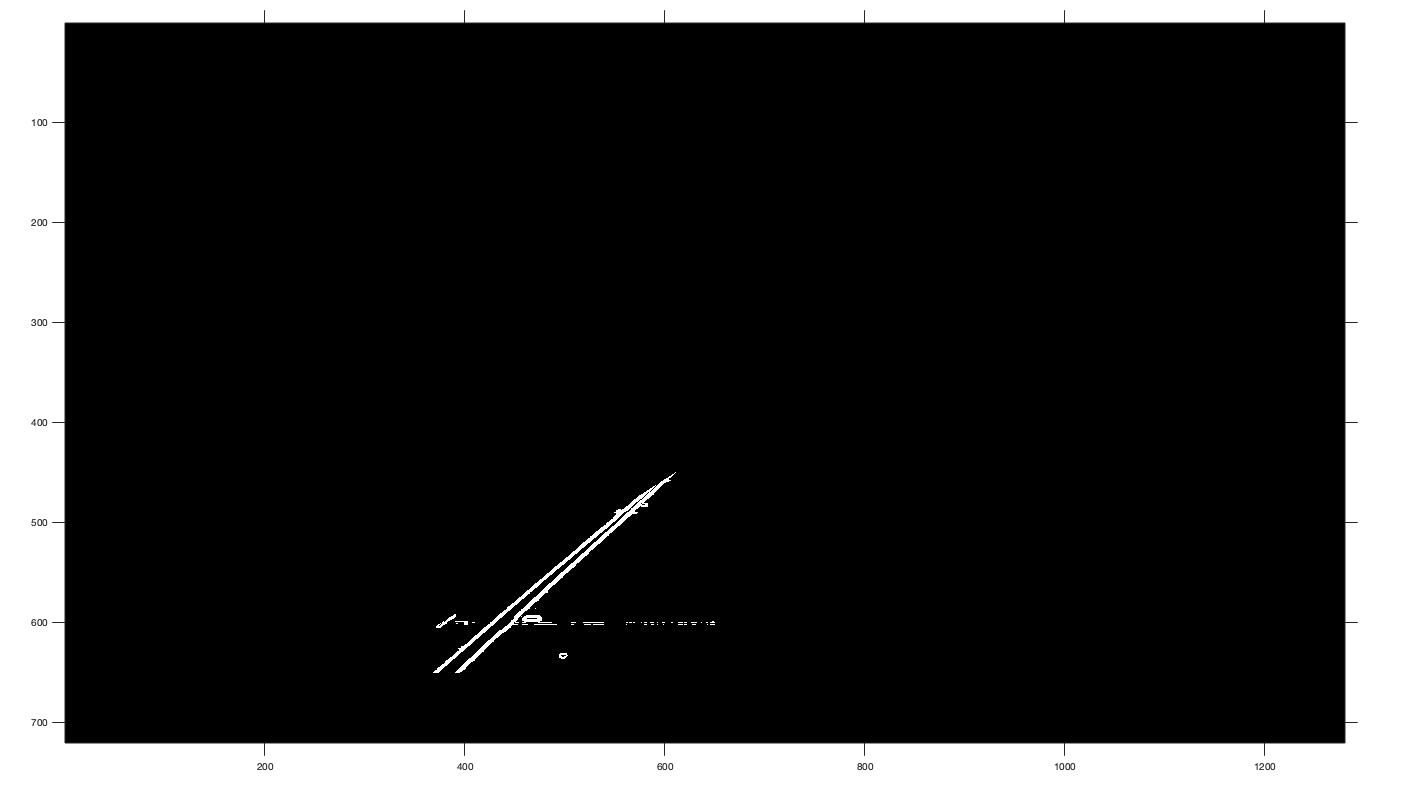

ln_x = [700, 680, 500, 200];
ln_y = [650, 300, 300, 650];
ln_mask = poly2mask(ln_x, ln_y, m, n);
masked_left = and(masked, ln_mask);
imshow(masked_left); axis on;

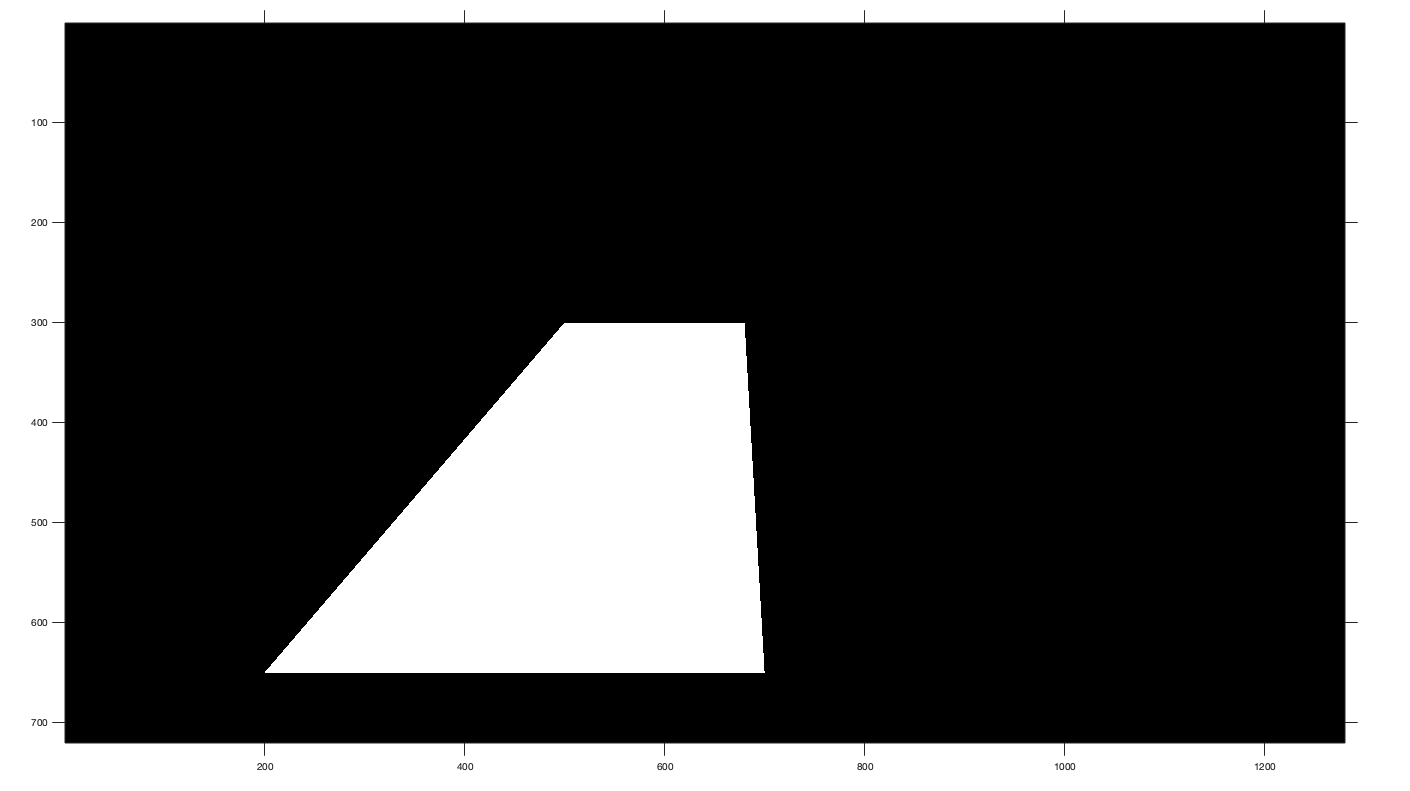

imshow(ln_mask)
axis on

imshow(masked); axis on;

[H, theta, rho] = hough(masked);

P = houghpeaks(H, 'threshold', 2);


    %----------Plotting Hough Transform and detecting Hough Peaks----------
    figure('Name','Hough Peaks for White Line')
    imshow(imadjust(rescale(H_W)),[],'XData',theta_W,'YData',rho_W,'InitialMagnification', 'fit');
    xlabel('\theta (degrees)')
    ylabel('\rho')
    axis on
    axis normal
    hold on
    colormap(gca,hot)
    x = theta_W(P_W(:,2));
    y = rho_W(P_W(:,1));
    plot(x,y,'s','color','blue');
    hold off
    % figure('Name','Hough Peaks for Yellow Line')
    % imshow(imadjust(rescale(H_Y)),[],'XData',theta_Y,'YData',rho_Y,'InitialMagnification', 'fit');
    xlabel('\theta (degrees)')
    ylabel('\rho')
    axis on
    axis normal
    hold on
    colormap(gca,hot)
    x = theta_W(P_Y(:,2));
    y = rho_W(P_Y(:,1));
    plot(x,y,'s','color','blue');
    hold off
    %--------------Extracting Lines from Detected Hough Peaks--------------
    lines_Y = houghlines(left_masked,theta_Y,rho_Y,P_Y,'FillGap',3000,'MinLength',20);
    figure('Name','Hough Lines found in image', 'visible', 'off'), imshow(img), hold on;
    if isempty(lines_Y) == false
        for k = 1:1
           xy = [lines_Y(k).point1; lines_Y(k).point2];
           plot(xy(:,1),xy(:,2),'LineWidth',2,'Color','green');
           % Plot beginnings and ends of lines
           plot(xy(1,1),xy(1,2),'x','LineWidth',2,'Color','yellow');
           plot(xy(2,1),xy(2,2),'x','LineWidth',2,'Color','red');
        end
    end

    lines_W = houghlines(right_masked,theta_W,rho_W,P_W,'FillGap',3000,'MinLength',20);
    max_len = 0;
    if isempty(lines_W) == false
        for k = 1:1
           xy = [lines_W(k).point1; lines_W(k).point2];
           plot(xy(:,1),xy(:,2),'LineWidth',2,'Color','red');
           % Plot beginnings and ends of lines
           plot(xy(1,1),xy(1,2),'x','LineWidth',2,'Color','blue');
           plot(xy(2,1),xy(2,2),'x','LineWidth',2,'Color','red');
        end
    end

v = VideoReader('Data/black_car.mp4');

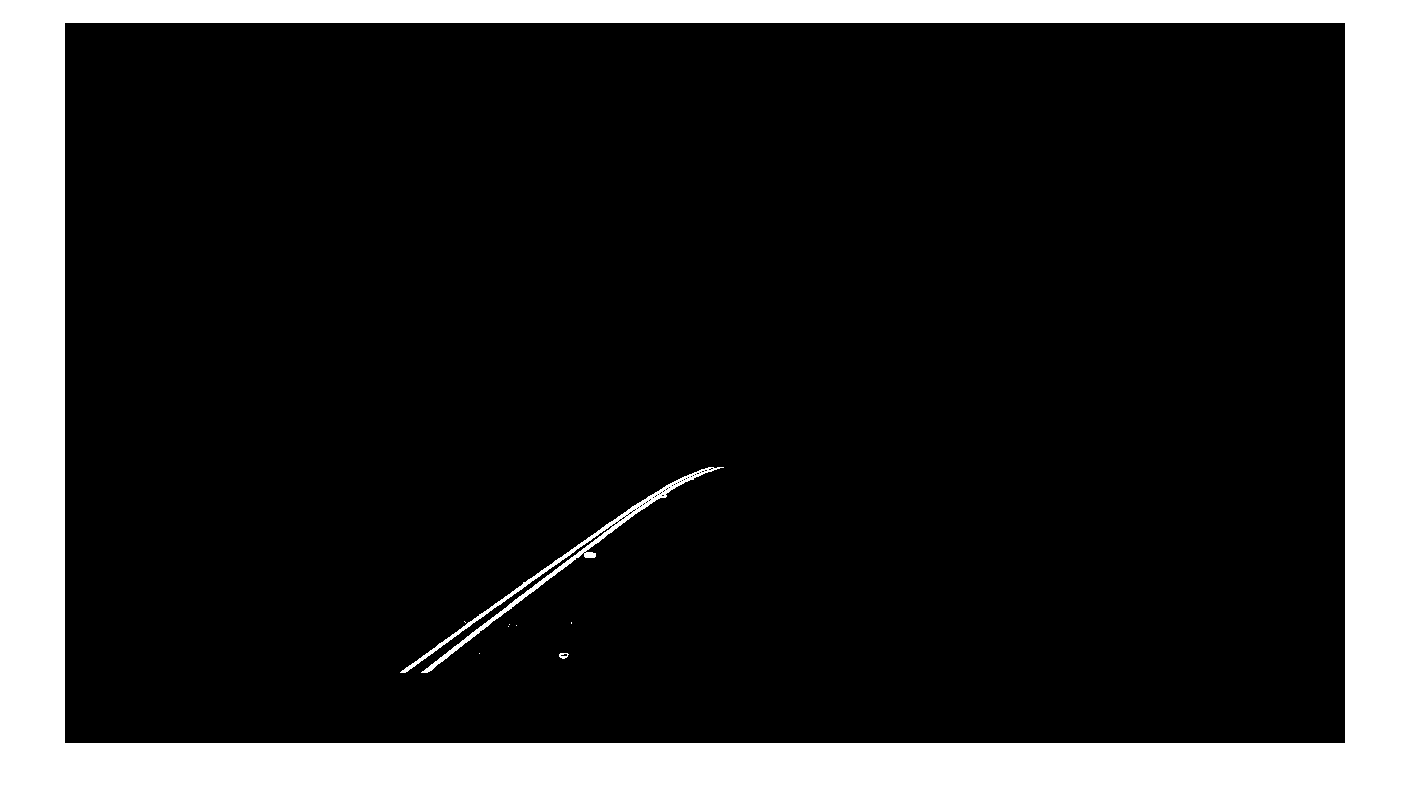

frame = readFrame(v);
[left, right] = pipes(frame);
imshow(right); imshow(left);

## Make thresholded video

v = VideoReader('Data/black_car.mp4');
outvid = VideoWriter('~/Desktop/masked_right.mp4', 'MPEG-4');
open(outvid);
while hasFrame(v)
    frame = readFrame(v);      % get frame
    hsv = rgb2hsv(frame);      % convert to hsv
    v_channel = hsv(:, :, 3);  % extract value channel from hsv
    sobel = imgradient(v_channel, 'sobel');
    a = imbinarize(sobel);
    masked = and(a, mask);
    masked_right = and(masked, rl_mask);
    writeVideo(outvid, double(masked_right));
end
close(outvid);

v = VideoReader('Data/black_car.mp4');
outvid = VideoWriter('~/Desktop/left_detection.mp4', 'MPEG-4');
open(outvid);
while hasFrame(v)
    X = pipes(frame, false);
    writeVideo(outvid, X);
end

close(outvid);

frame = readFrame(v);
[left, right, X] = pipes(frame, false);
% imshow(right)

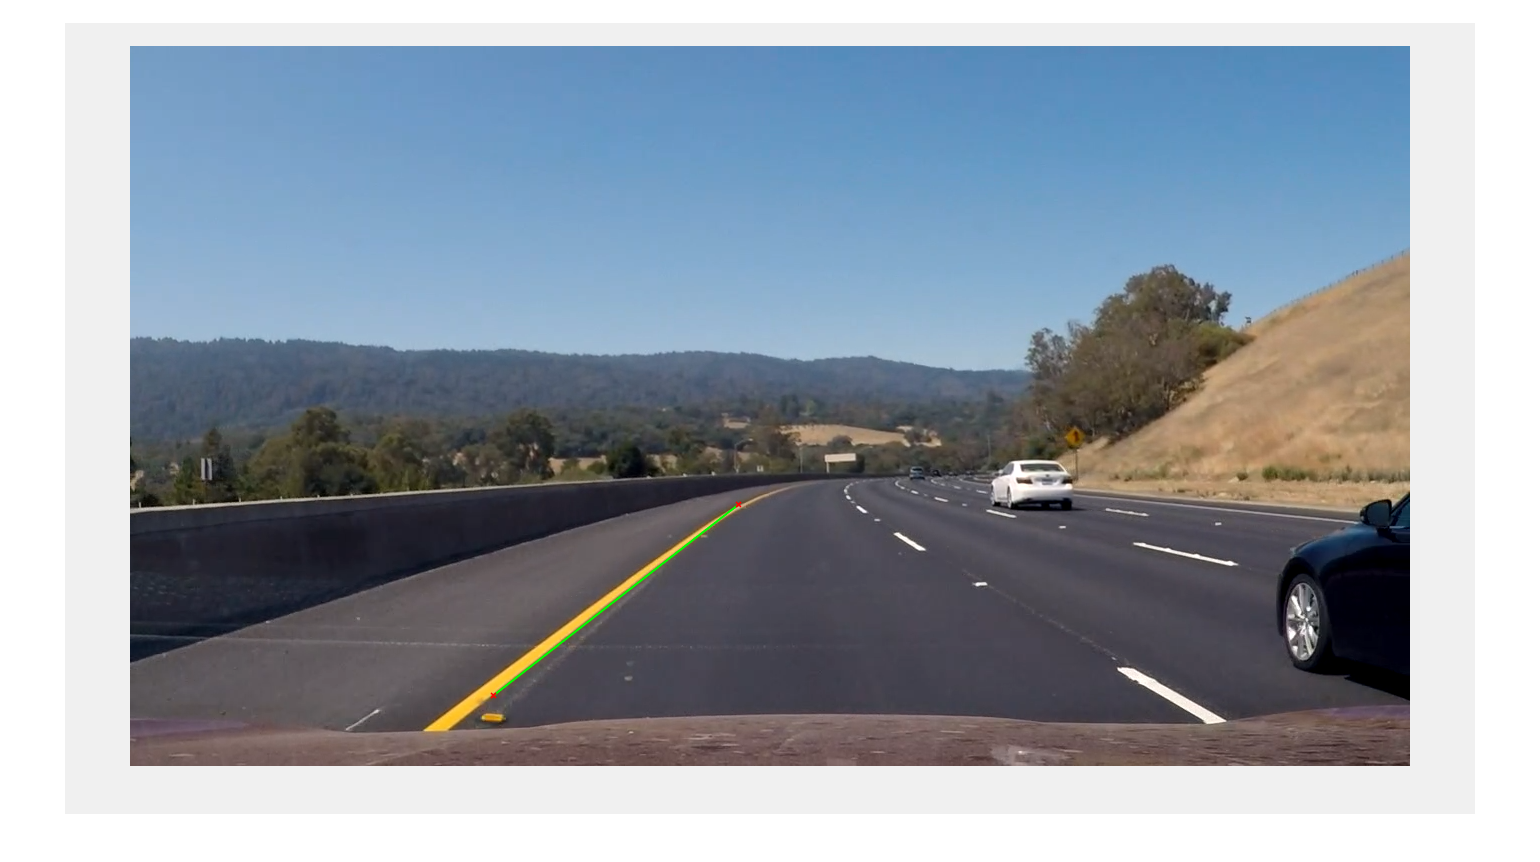

imshow(X)

    function X = pipes(frame, show_hough)
        %% Convert from RGB to HSV
        hsv = rgb2hsv(frame);
        v_channel = hsv(:, :, 3);
        %% Threshold Image
        sobel = imgradient(v_channel, 'sobel');
        a = imbinarize(sobel);
        %% Mask Image
        dimens = size(a);
        m = dimens(1);
        n = dimens(2);
        x_points = [710, 620, 190, 1230];
        y_points = [444, 444, 720, 720];
        rl_x = [710, 680, 680, 1200];
        rl_y = [200, 200, 650, 650];
        ll_x = [700, 680, 500, 200];
        ll_y = [650, 300, 300, 650];
        mask = poly2mask(x_points, y_points, m, n);
        rl_mask = poly2mask(rl_x, rl_y, m, n);
        ln_mask = poly2mask(ll_x, ll_y, m, n);
        masked = and(a, mask);
        masked_left = and(masked, ln_mask);
        masked_right = and(masked, rl_mask);
        %% Hough Points
        [H_l, theta_l, rho_l] = hough(masked_left);
        P_l = houghpeaks(H_l, 2, 'threshold', 2);
        [H_r, theta_r, rho_r] = hough(masked_right);
        P_r = houghpeaks(H_r, 2, 'threshold', 2);
        
        if show_hough == true
            figure('Name', 'Hough Peaks for Left Line');
            imshow(imadjust(rescale(H_l)), [], 'XData', theta_l, 'YData', rho_l, 'InitialMagnification', 'fit');
            xlabel('\theta (degrees)');
            ylabel('\rho');
            axis on;
            axis normal;
            hold on;
            colormap(gca,hot);
            x = theta_l(P_l(:, 2));
            y = rho_l(P_l(:, 1));
            plot(x, y, 's', 'color', 'blue');
            title('Hough Peaks for Left Line');
            hold off;
            
            figure('Name', 'Hough Peaks for Right Line');
            imshow(imadjust(rescale(H_r)), [], 'XData', theta_r, 'YData', rho_r, 'InitialMagnification', 'fit');
            xlabel('\theta (degrees)');
            ylabel('\rho');
            axis on;
            axis normal;
            hold on;
            colormap(gca, hot);
            x = theta_r(P_r(:, 2));
            y = rho_r(P_r(:, 1));
            plot(x, y, 's', 'color', 'blue');
            title('Hough Peaks for Right Line');
            hold off;
        end

        
        
        %% Extracct lines from Hough Peaks
        lines_left = houghlines(masked_left, theta_l, rho_l, P_l, 'FillGap', 3000, 'MinLength', 20);
% %         figure('Name', 'Hough Lines found in image', 'visible', 'off'), imshow(frame), hold on;
        figure('Name','Hough Lines found in image', 'visible', 'off'), imshow(frame), hold on;
        if isempty(lines_left) == false
            xy = [lines_left(1).point1; lines_left(1).point2];
            plot(xy(:,1), xy(:,2), 'LineWidth', 2, 'Color', 'green');
            plot(xy(1,1), xy(1,2), 'x', 'LineWidth', 2, 'Color', 'red');
            plot(xy(2,1), xy(2,2), 'x', 'LineWidth', 2, 'Color', 'red');
        end
        
        F = getframe(gcf);
        [X, Map] = frame2im(F);
       
        
    end